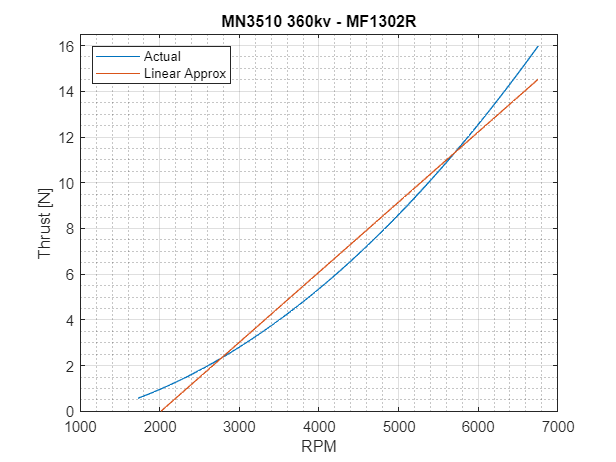

addpath(genpath('C:\Users\Tomaso\Desktop\Thesis\main\export_figures'))

%%% Thrust curve %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
rpm = linspace(1725,6755);
p = [3.48110501101274e-07,0.000110721041067758,-0.650737650838279];
T = polyval(p,rpm);
T2 = polyval(polyfit(rpm,T,1),rpm);
figure(1)
clf
plot(rpm,T)
hold on
plot(rpm,T2)
ylim([0,16.5])
xlabel('RPM')
ylabel('Thrust [N]')
grid on
grid minor
legend("Actual","Linear Approx",'Location','northwest')
title('MN3510 360kv - MF1302R')
width = 3;     % Width in inches
height = 3;    % Height in inches
set(gcf,'InvertHardcopy','on');
set(gcf,'PaperUnits', 'inches');
papersize = get(gcf, 'PaperSize');
left = (papersize(1)- width)/2;
bottom = (papersize(2)- height)/2;
myfiguresize = [left, bottom, width, height];
set(gcf,'PaperPosition', myfiguresize);
rmse = rms((T2-T));

export_fig thrust_curve.pdf

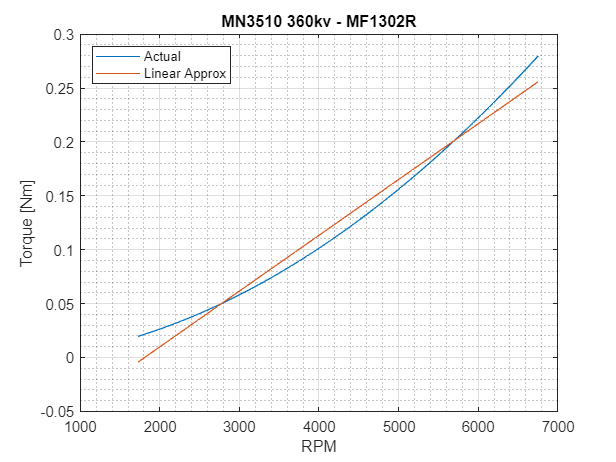


%%% Thrust curve %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
rpm = linspace(1725,6755);
p = [5.730e-9,3.124e-6,-2.80e-3];
Q = polyval(p,rpm);
Q2 = polyval(polyfit(rpm,Q,1),rpm);
figure(2)
clf
plot(rpm,Q)
hold on
plot(rpm,Q2)
%ylim([0,16.5])
xlabel('RPM')
ylabel('Torque [Nm]')
grid on
grid minor
legend("Actual","Linear Approx",'Location','northwest')
title('MN3510 360kv - MF1302R')
width = 3;     % Width in inches
height = 3;    % Height in inches
set(gcf,'InvertHardcopy','on');
set(gcf,'PaperUnits', 'inches');
papersize = get(gcf, 'PaperSize');
left = (papersize(1)- width)/2;
bottom = (papersize(2)- height)/2;
myfiguresize = [left, bottom, width, height];
set(gcf,'PaperPosition', myfiguresize);
rmse = rms((Q2-Q));

export_fig torque_curve.pdf